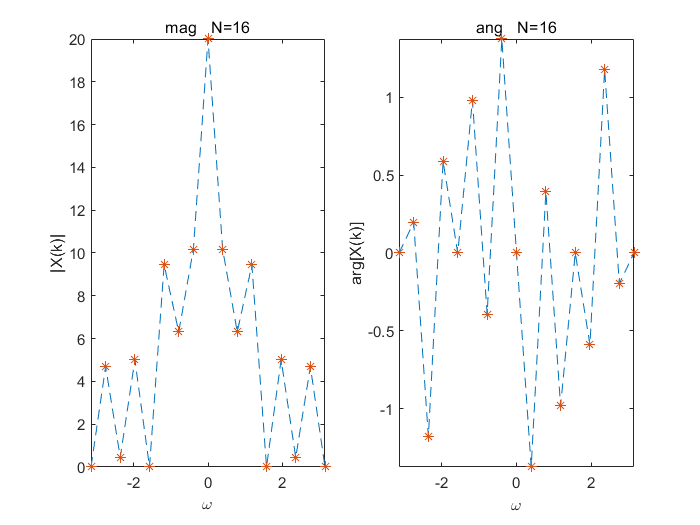

clc;
clear

N1 = 8;
N2 = 16;
N = N2;
n = 0:N-1;
x1 = ones(1, 4);
x2 = [1:4 4:-1:1];
x3 = [4:-1:1 1:4];
x4 = cos(pi/4 * n);
x5 = sin(pi/8 * n);


x_n = x3;
[k, x_n, ~] = fft_anylsis(x_n, N, 1);

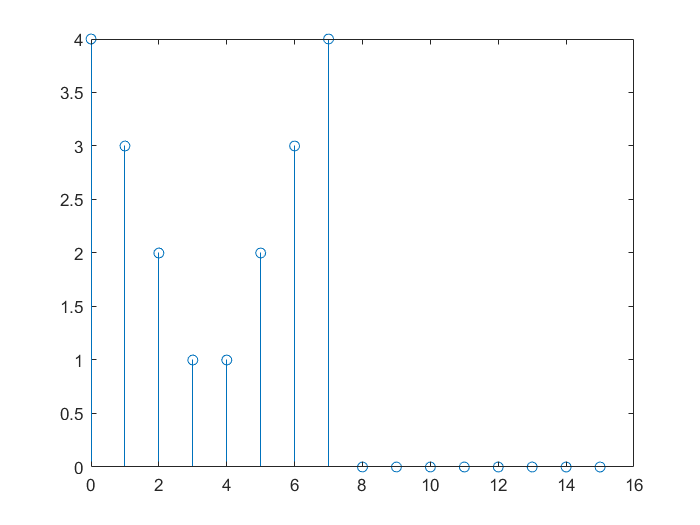

figure
stem(n, x_n);
axis([0 N -inf inf])

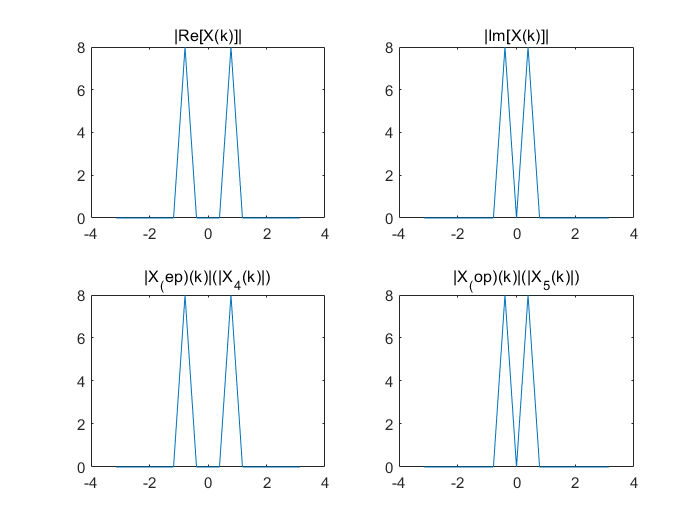

% EXP-2
N = 16;
x_n = x4+x5;

[k, x_n, mag_X_k, ang_X_k, re_X_k, im_X_k] = fft_anylsis(x_n, N, 0);
[k, x4a, mag_x4, ~] = fft_anylsis(x4, N, 0);
[k, x5a, mag_x5, ~] = fft_anylsis(x5, N, 0);

subplot(2, 2, 1)
plot(k, re_X_k)
title('|Re[X(k)]|')

subplot(2, 2, 2)
plot(k, abs(im_X_k))
title('|Im[X(k)]|')

subplot(2, 2, 3)
plot(k, mag_x4)
title('|X_(ep)(k)|(|X_4(k)|)')

subplot(2, 2, 4)
plot(k, mag_x5)
title('|X_(op)(k)|(|X_5(k)|)')

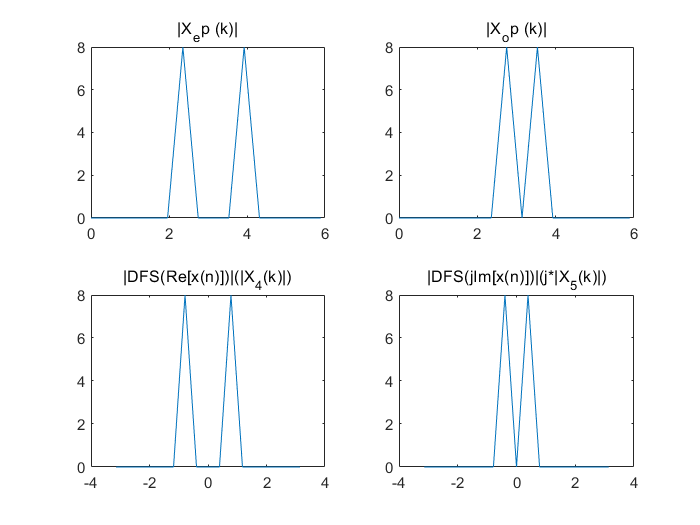

N = 16;
n = 0:N-1;
D = 2*pi/N;
n = D*n;
x_n = x4+1j* x5;

X_k = fft(x_n);

[k, x4a, mag_x4, ~] = fft_anylsis(x4, N, 0);
[k, x5a, mag_x5, ~] = fft_anylsis(x5, N, 0);

[xep, xop] = circevod(X_k);
xep = fftshift(xep);
xop = fftshift(xop);

subplot(2, 2, 1)
plot(n, abs(xep))
title('|X_ep (k)|')

subplot(2, 2, 2)
plot(n, abs(xop))
title('|X_op (k)|')

subplot(2, 2, 3)
plot(k, mag_x4)
title('|DFS(Re[x(n)])|(|X_4(k)|)')

subplot(2, 2, 4)
plot(k, mag_x5)
title('|DFS(jIm[x(n)])|(j*|X_5(k)|)')

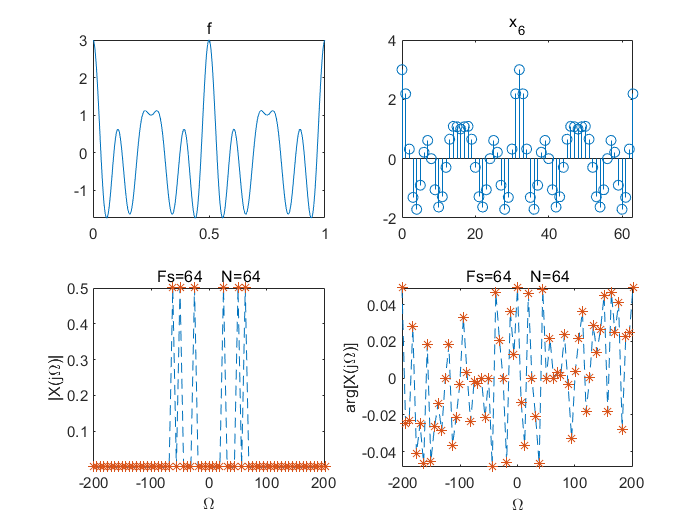

% 对x_6 进行谱分析
clc;
clear
f =@(t) cos(8*pi*t) + cos(16*pi*t) + cos(20*pi*t);
Fs = 64;
T = 1/Fs;
N = 64; % 32, 64

n = 0:N-1;
x_6 = f(n*T);

[k, x_6, mag_x, ang_x, ~] = fft_anylsis(x_6, N, 0);
mag_x = T*mag_x; ang_x = T*ang_x;
subplot(2, 2, 1)
fplot(f, [0, N*T])
title('f')

subplot(2, 2, 2)
stem(n, x_6)
title('x_6')

subplot(2, 2, 3)
plot(k*Fs, mag_x, '--');
axis([-Fs*pi, Fs*pi, -inf, inf])
xlabel('\Omega')
ylabel('|X(j\Omega)|')
title(['Fs=', num2str(Fs), '    N=', num2str(N)])
hold on
plot(k*Fs, mag_x, '*')
hold off

subplot(2, 2, 4)
plot(k*Fs, ang_x, '--');
axis([-Fs*pi, Fs*pi, -inf, inf])
xlabel('\Omega')
ylabel('arg[X(j\Omega)]')
title(['Fs=', num2str(Fs), '    N=', num2str(N)])
hold on
plot(k*Fs, ang_x, '*')
hold off

function [k, x_n, mag_X_k, ang_X_k, re_X_k, im_X_k, X_k] = fft_anylsis(x_n, N, anylsis)
    M = length(x_n);
    x_n = [x_n zeros(1, N-M)];
    
    X_k = fftshift(fft(x_n));
    X_k(N+1) = X_k(1); % 多补充一位以利于体现对称性（在n=(N+1)/2 处补上 n=-(N-1)/2的值 相当于将序列在圆周上\pi处排列的值重复一遍）
    
    k = floor(-(N-1)/2:(N+1)/2);
    k = k .* (2 * pi / N);
    
    mag_X_k = abs(X_k);
    ang_X_k = angle(X_k);
    
    re_X_k = real(X_k);
    im_X_k = imag(X_k);
    
    if anylsis
        subplot(1, 2, 1)
        plot(k, mag_X_k, '--');
        axis([-pi, pi, -inf, inf]);
        xlabel('\omega')
        ylabel('|X(k)|')
        title(['mag   ', 'N=', num2str(N)])
        hold on 
        plot(k, mag_X_k, '*');
        hold off 
        
        subplot(1, 2, 2)
        plot(k, ang_X_k, '--');
        axis([-pi, pi, -inf, inf]);
        xlabel('\omega')
        ylabel('arg[X(k)]')
        title(['ang   ', 'N=', num2str(N)])
        hold on 
        plot(k, ang_X_k, '*');
        hold off
    end
end

function [xep, xop] = circevod(x)
    N = length(x); n = 0:N-1;
    
    xep = .5*(x +x(mod(-n, N)+1));
    xop = .5*(x -conj(x(mod(-n, N)+1)));
end